# **RS-HL-12: Multi User Result Display**

**Hongseok Kim**

**UT Austin Oden Institute**

**07/22/2024**

## I. 2D plot

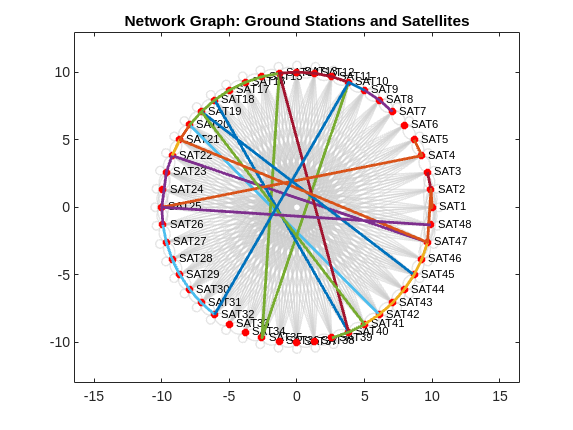

% Number of ground stations and satellites
num_sats = 48;

% Create a graph object
G = graph();

% Load the Satellite Contact Matrix
Sat_to_Sat = sat_to_sat_contact_3d_matrix(:,:,time_index);

% Add Satellites as nodes
for i = 1:num_sats
    G = addnode(G, sprintf('SAT%d', i));
end


% Add edges between Satellites
for i = 1:num_sats
    for j = 1:num_sats
        if Sat_to_Sat(i, j) == 1
            G = addedge(G, sprintf('SAT%d', i), sprintf('SAT%d', j));
        end
    end
end

pi = 3.1415026535;
satellite_radius = 10;

% Satellite positions
satellite_angles = linspace(0, 2*pi, num_sats+1);
satellite_angles = satellite_angles(1:end-1);
satellite_x = satellite_radius * cos(satellite_angles);
satellite_y = satellite_radius * sin(satellite_angles);

% Plot the network graph
figure;
plot(G, 'XData', satellite_x, 'YData', satellite_y, 'NodeColor', [0.6 0.6 0.6], 'EdgeColor', [0.8 0.8 0.8], 'LineWidth', 1);
hold on;

% Plot the ground stations in blue and the satellites in red
plot(satellite_x, satellite_y, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');



result_sort = result(:,2:end);
number_of_agents = length(result_sort(1,:));


for agent_index = 1:number_of_agents-1

pathway_for_agent = result_sort(:,agent_index);
simulation_result = pathway_for_agent(pathway_for_agent ~= 0);

Data_Transmission_Sequence = zeros(length(simulation_result),2);

    for ii = 1:length(simulation_result)
        Data_Transmission_Sequence(ii,:) = [satellite_x(simulation_result(ii)), satellite_y(simulation_result(ii))];
    end
plot(Data_Transmission_Sequence(:,1),Data_Transmission_Sequence(:,2), 'MarkerSize', 3, 'MarkerFaceColor', 'G')
plot(Data_Transmission_Sequence(:,1),Data_Transmission_Sequence(:,2),'LineWidth',2);
end

hold off
axis equal;
title('Network Graph: Ground Stations and Satellites');

## II. 3D plot

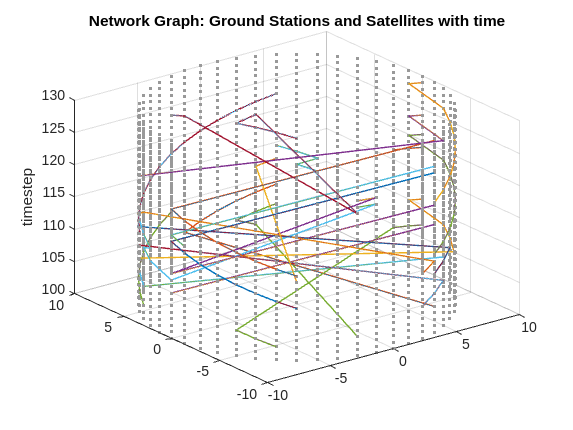

% Satellite positions
num_sats = 48;

satellite_angles = linspace(0, 2*pi, num_sats+1);
satellite_angles = satellite_angles(1:end-1);
satellite_x = satellite_radius * cos(satellite_angles);
satellite_y = satellite_radius * sin(satellite_angles);

for t = time_index_vector
    z_position = ones(length(satellite_x))*t;
    scatter3(satellite_x,satellite_y,z_position,'.','MarkerEdgeColor', [0.6 0.6 0.6])
    hold on
end

result_sort = result(:,2:end);
number_of_agents = length(result_sort(1,:));


for agent_index = 2:number_of_agents+1

pathway_for_agent = result(:,[1,agent_index]);
simulation_result = pathway_for_agent(pathway_for_agent(:,2)~=0,:);

Data_Transmission_Sequence = zeros(length(simulation_result(:,1)),3);

    for ii = 1:length(simulation_result(:,1))
        Data_Transmission_Sequence(ii,:) = [satellite_x(simulation_result(ii,2)), satellite_y(simulation_result(ii,2)), simulation_result(ii,1)];
    end

plot3(Data_Transmission_Sequence(:,1),Data_Transmission_Sequence(:,2),Data_Transmission_Sequence(:,3), 'MarkerSize',3)
plot3(Data_Transmission_Sequence(:,1),Data_Transmission_Sequence(:,2),Data_Transmission_Sequence(:,3),'LineWidth',1);
hold on
end
hold off
title('Network Graph: Ground Stations and Satellites with time');
zlabel('timestep')